##  Задание 2. Еще одно исследование управляемости. 

Начальные условия на задание:

A = [3, -6, 4; 
     4, -5, 4;
     -4, 4, -5]

A =      3    -6     4
     4    -5     4
    -4     4    -5


B = [11;
      7;
      -7]

B =     11
     7
    -7


x1 = [1; % x1'
      0;
      0]

x1 =      1
     0
     0


x2 = [0; % x1''
      0;
      1]

x2 =      0
     0
     1


Проверяем точки x1,x2 на принадлежность к управляемому подпространству системы:

Условие принадлежности точки: **rank( U ) == rank( [ U x1 ] )**

U = [B , A*B , A^2 * B]

U =     11   -37    79
     7   -19    23
    -7    19   -23


% rangeU = range(U)
rank(U)

ans = 2

rank([U, x1])

ans = 2

rank([U, x2])

ans = 3

*x1 принадлежит, x2 --> нет*

Теперь повторяем шаги из задания 1

Исследовать управляемость системы по трём критерям:

Проверка критерия Калмана

U = [B , A*B , A^2 * B]

U =     11   -37    79
     7   -19    23
    -7    19   -23


rank(U)

ans = 2

Проверка критерия Хаутуса:

eig(A)

ans =   -3.0000 + 2.0000i
  -3.0000 - 2.0000i
  -1.0000 + 0.0000i


l1 = -3 + 2j; l2 = -3 - 2j; l3 = -1;

[A - eye(3).*l1 , B]

ans =    6.0000 - 2.0000i  -6.0000 + 0.0000i   4.0000 + 0.0000i  11.0000 + 0.0000i
   4.0000 + 0.0000i  -2.0000 - 2.0000i   4.0000 + 0.0000i   7.0000 + 0.0000i
  -4.0000 + 0.0000i   4.0000 + 0.0000i  -2.0000 - 2.0000i  -7.0000 + 0.0000i


[A - eye(3).*l2 , B]

ans =    6.0000 + 2.0000i  -6.0000 + 0.0000i   4.0000 + 0.0000i  11.0000 + 0.0000i
   4.0000 + 0.0000i  -2.0000 + 2.0000i   4.0000 + 0.0000i   7.0000 + 0.0000i
  -4.0000 + 0.0000i   4.0000 + 0.0000i  -2.0000 + 2.0000i  -7.0000 + 0.0000i


[A - eye(3).*l3 , B]

ans =      4    -6     4    11
     4    -4     4     7
    -4     4    -4    -7



rank([A - eye(3).*l1 , B]) % устойчивая собственное число

ans = 3

rank([A - eye(3).*l2 , B]) % устойчивая собственное число

ans = 3

rank([A - eye(3).*l3 , B]) % не-а

ans = 2

Проверка критерия по Жордану (функция в матлабе немного криво реализована):

[P, Aj] = jordan(A);
[P2, Aj2] = cdf2rdf(P, Aj);

Aj2  % теперь их соотносим

Aj2 =     -1     0     0
     0    -3    -2
     0     2    -3


P^-1 * B    % теперь их соотносим

ans =    0.0000 + 0.0000i
  -3.5000 - 0.5000i
  -3.5000 + 0.5000i


- Все Жордановы клетки относятся к различным собственными числам - ДА

- Элементы матрицы входных воздействий, соответствующие последним строкам жордановых клеток не равны 0.

Собственное число -1 --> **нет, **ведь там ноль стоит

Собственное число комплексное --> 

"Для комплексных не кратных можно  управлять Жордановой  клеткой хоть через  верхнюю строку, хоть  через нижнюю, система  все еще управляема"

И  ответ будет **да**, и там и там -2.1 стоит...

В итоге система в жордановой форме **не полностью управляема**

Найти Грамиан...

Считаем Граммиан по определению

t1 = 3;
% syms  ломает подсчёт интеграла, которые связан с переменной анонимной
% функции t.... 

% syms t
% expr = expm(A*t) * B * (B.') * expm( (A.') * t);
% F = int(expr,t, [0 t1]);
% integral_cutted = double(vpa(F)) 
% eig_values_gram = eig(integral_cutted)

Попробуем конкретной функцией получим Граммиан

C = zeros([1, 3]); D = zeros([1, 1]);
sys = ss(A,B,C,D)

sys =
 
  A = 
       x1  x2  x3
   x1   3  -6   4
   x2   4  -5   4
   x3  -4   4  -5
 
  B = 
       u1
   x1  11
   x2   7
   x3  -7
 
  C = 
       x1  x2  x3
   y1   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


control_gram = gram(sys, 'c')

control_gram =    15.4744   10.6923  -10.6923
   10.6923    7.4744   -7.4744
  -10.6923   -7.4744    7.4744


observe_gram = gram(sys, 'o');
eig_values_gram = eig(control_gram)

eig_values_gram =    -0.0000
    0.0880
   30.3350


Мы получили, что одно из собственных чисел равно нулю, значит то, что матрица Грамиана управляемости  - положительно полуопределённой, значит систему не полностью управляема.

Найти управление, выполнить моделирование по нему

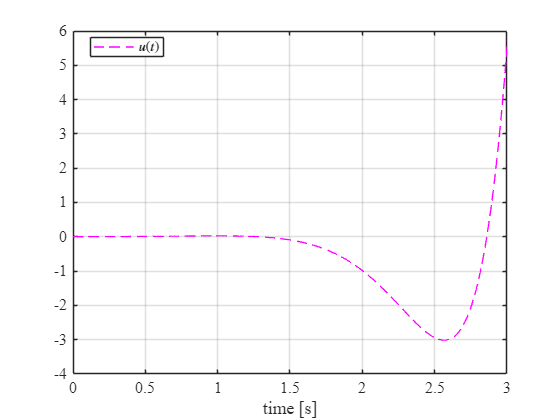

time = linspace(0, t1, 1000);
u_values = zeros(size(time)); 
t_values = zeros(3, length(time)); 


u = @(t) (B.') * expm((A.') * (t1 - t)) * (control_gram^-1) * x1;

for i = 1:length(time)
    u_values(i) = u(time(i));
end

expmA = @(t) expm(A * (t1 - t) ) * B * u(t);

for i = 1:length(time)
    t_values(:, i) = integral(expmA, 0 , time(i), 'ArrayValued',true); 
end

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, u_values, 'magenta--', 'LineWidth', 1.0); 
title(' ');
xlabel('time [s]');                  
grid on;
legend('$u(t)$', 'Location', 'best', 'Interpreter', 'latex');
save_file("control2");
xlim([0.0, 3.0])

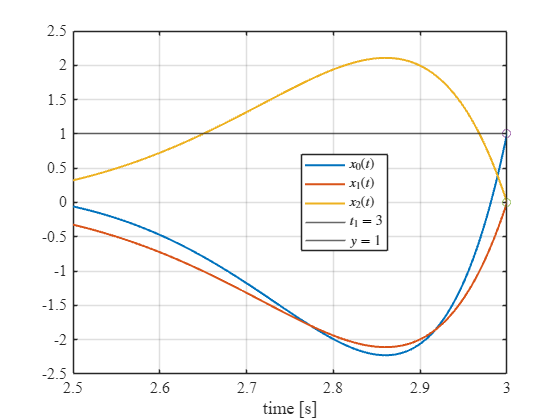

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, t_values(1, :), 'LineWidth', 1.5); hold on;
plot(time, t_values(2, :), 'LineWidth', 1.5);
plot(time, t_values(3, :), 'LineWidth', 1.5);
xline(3, '-'); yline(1, '-'); plot(3, 1, 'o');plot(3, 0, 'o') 
title(' ');   
xlabel('time [s]');                  
grid on;
legend('$x_0(t)$', '$x_1(t)$', '$x_2(t)$', '$t_1 = 3$', '$y = 1$', ...
       'Location', 'best', 'Interpreter', 'latex');
xlim([2.5, 3.0])
save_file("controlability2");

**Функция, чтобы сохранить картинку в папку**

function save_file(name)
    path = 'D:\Math\control_theory\control_theory_labs\lab7\latex7\images';
    fullpath = fullfile(path, name);
    saveas(gcf, fullpath, 'png');

end